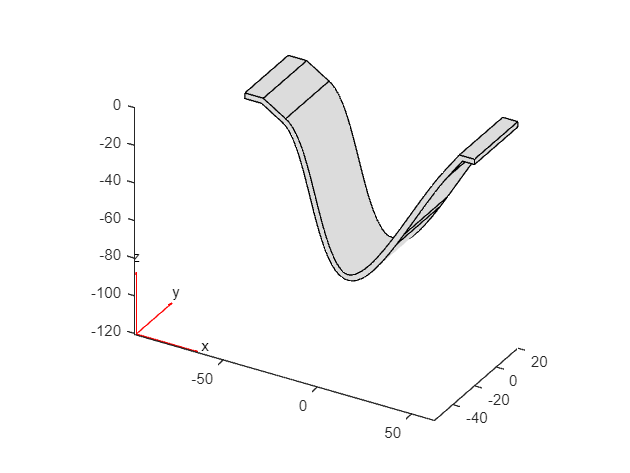

figure
gm= importGeometry(".\models\SectionExtruded v1.stl"); % input
pdegplot(gm)

[modelT,~,~,~] = stlread(".\models\SectionExtruded v1.stl");
start_point = [-55 -20 0];
end_point = [40 -20 0];
preform_angle = 65;
pointsPerFacet = 50;
[sectionPoints,preformedSectionPoints] = preformSectionPoints(modelT,start_point,end_point,preform_angle,pointsPerFacet);

    "162"    "facets found in this section"

    "-30.7911"    "20"    "-18.1288"    "-5.46415"    "20"    "-80.7709"    "are the points wh…"

   -5.4641   20.0000  -80.7709

   162

    "-Inf"    "z_max"



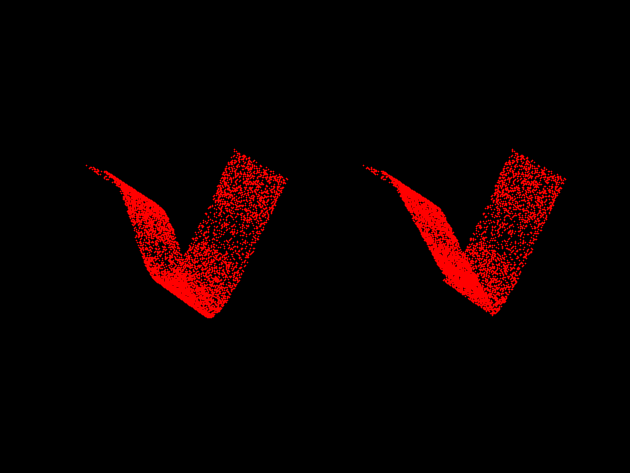

ptCld = pointCloud(sectionPoints,"Color","red");
ptCld2 = pointCloud(preformedSectionPoints,"Color","red");
figure
subplot(1,2,1);
pcshow(ptCld)
subplot(1,2,2);
pcshow(ptCld2)

v1 = [1 2 1];
v2 = [-1 2 -1];
v3 = [-100 3 -2];
v = [v1;v2;v3];
v = sortrows(v,1,"ascend")

v =   -100     3    -2
    -1     2    -1
     1     2     1


vx = [1 2];
v3(2) = vx(2);
v(2);
x = min(v,[],2)

x =   -100
    -1
     1


### `preformSectionPoints `(for exturuded section):

Assumptions:

- The tool comes along z-axis, the surface is extruded along y-axis

Algorithm:

- find the extrema points on either sides `(p1,p2)` of the section where the wall angle,$\theta >\alpha ,$preform angle.

- for each facet in the section, put a fixed number of random points

- for each point :   

                   if it is before `p1 `or `p2 `leave it **as is**

                   if it is after `p1 or p2 `and the projected cone surface is above the original surface, **shift ** it to the cone surface

                  if it is after `p1 or p2 `and the projected cone surface is below the original surface, stop assigning cone surface and

                  **shift** it to a flat horizontal surface. Where the horizontal surface is the z-plane that has the hightest point which suits

                 the above criterion.

function [sectionPoints,preformedSectionPoints] = preformSectionPoints(modelT,startPoint,endPoint,performAngle,pointsPerFacet)
     m = size(modelT.ConnectivityList,1);
     
     % scan the section for limiting-angle-poisition
     p1 = startPoint; p2 = endPoint;pMin = endPoint;
     facetsInSection = 0;
     for facet = 1:m
         [inSection,v] = isFacetInSection(modelT,facet,startPoint,endPoint);
         if(inSection == false)
             continue
         end
         facetsInSection = facetsInSection+1;
         face_normal = faceNormal(modelT,facet);
         
        if(acosd(face_normal(3)) >= performAngle)
            if(p1(1) < v(1,1))
                p1 = v(1,:);
            elseif(p2(1) > v(3,1))
                p2 = v(3,:);
            end
        end

        v_ = sortrows(v,3,"ascend");
        if(v_(1,3) <= pMin(3))
            pMin = v_(1,:);
        end

     end

     tmp = p1; p1 = p2;  p2 = tmp;
     if(p1(1)>pMin(1))
         p1 = pMin;
     elseif(p2(1)<pMin(1))
         p2 = pMin;
     end

     disp([facetsInSection "facets found in this section"])
     disp([p1 p2 "are the points where the angle becomes greater than preform angle"])
     disp(pMin)

     preformedSectionPoints = ones(pointsPerFacet*facetsInSection,3)*Inf;
     sectionPoints = ones(pointsPerFacet*facetsInSection,3)*Inf;
     x1_ = p1(1)+(p1(3)-p2(3))/tand(performAngle);
     coneVertX = (x1_+p2(1))/2;
     z_max = Inf*-1;
     currentFacet =0;


     for facet=1:m
         [inSection,v] = isFacetInSection(modelT,facet,startPoint,endPoint);
         if(inSection == false)
             continue
         end
       
        randPoints = randPointsOnFacet(v,pointsPerFacet);
        sectionPoints(currentFacet*pointsPerFacet+1:(currentFacet+1)*pointsPerFacet,:) = randPoints;
        
        for pt=1:pointsPerFacet % z_cone calculation
            if(p1(1) <= randPoints(pt,1) && coneVertX >= randPoints(pt,1))
                z = p1(3)-(randPoints(pt,1)-p1(1))*tand(performAngle);
            elseif (coneVertX <= randPoints(pt,1) && p2(1) >= randPoints(pt,1))
                z = p2(3)-(p2(1)-randPoints(pt,1))*tand(performAngle);
            else % the point is before the region where preform = final form
                preformedSectionPoints(currentFacet*pointsPerFacet+pt,:) = randPoints(pt,:);
                continue
            end
            
            if(z > randPoints(pt,3)) % cone should be put
                preformedSectionPoints(currentFacet*pointsPerFacet+pt,:) = randPoints(pt,:);
                preformedSectionPoints(currentFacet*pointsPerFacet+pt,3) = z;
            else % donot update the preform and leave as Inf
                z_max = max(randPoints(pt,3),z_max);
            end
        end
        currentFacet = currentFacet+1;     
     end

     disp([z_max "z_max"])

     if(z_max ~= Inf*-1) %%some correction needed here
         disp("Preform was on top")
         for pt = 1:size(sectionPoints,1)
             if(preformedSectionPoints(pt,3) == Inf)
                 preformedSectionPoints(pt,:) = sectionPoints(pt,:);
                 preformedSectionPoints(pt,3) = z_max;
             end
         end
     end
     
     return
end

### `isFacetInSection `(for extruded section):

Assumptions:

- The surface is extruded along y-axis

- The stl file contains a *surface, not solid*

Algorithm:

- The facet belongs to the section if all 3 veritces of the facet are within the x-limits of the section

function [inSection,vertices] = isFacetInSection(modelT,facetID,startPoint,endPoint)
      inSection = true;
      vertices = zeros(3,3);
      facenormal = faceNormal(modelT,facetID);
      if(facenormal(3) <= 0) % ignore outer facets
        inSection = false;
        return
      end

     v1 = modelT.Points(modelT.ConnectivityList(facetID,1),:);
     v2 = modelT.Points(modelT.ConnectivityList(facetID,2),:);
     v3 = modelT.Points(modelT.ConnectivityList(facetID,3),:);

     v = [v1; v2; v3];
     v = sortrows(v,1,"ascend");

     for vertex = 1:3
         if(v(vertex,1) < startPoint(1) || v(vertex,1) > endPoint(1))
            inSection = false;
            return
         end
     end

     vertices = v;
end


### `randPointsOnFacet`

Assumptions:

- Any triangle in 3D

Algorithm:

- $\alpha *\vec{\textrm{v1}} +\beta *\vec{\textrm{v2}} +\gamma *\vec{\textrm{v3}} =\vec{p} \;$is a point in triagle with vertices $\vec{\textrm{v1}} ,\vec{\textrm{v2}} \;\textrm{and}\;\vec{\textrm{v3}}$, where $\alpha +\beta +\gamma =1\;\mathrm{for}\;\mathrm{positive}\;\mathrm{values}\;\mathrm{of}\;\alpha ,\beta ,\gamma$

function [randPoints] = randPointsOnFacet(vertices,pointsPerFacet)
    randPoints = ones(pointsPerFacet,3);

    for j = 1:pointsPerFacet  % create certain number of random points inside the facet
        a = rand();
        b = rand();
        if (a+b > 1)
            a = 1-a;
            b = 1-b;
        end
        pnt = vertices(1,:)*a+vertices(2,:)*b+vertices(3,:)*(1-a-b);
        randPoints(j,:) = pnt;
    end

end